clc,clear,close all
global hstep
global Element
global Center
global M2

设置方程

% u0 = @(x) 1/4+1/2*sin(pi*x);   % 初值
u0 = @(x) sin(pi*x);   % 初值
left = -1;              % 求解区间
right = 1;              % 求解区间
time = 0.1;             % 时间
num = 20;               % 区间数量

分配内存

Num = num+2;                        % 周期边界条件，左右各加一个区间后，区间数量
delta_t = 0.1*(right-left)/num;     % 时间步长
hstep = (right-left)/num;           % 每个区间的长度，这里设置成等长。
Element_l = left-hstep:hstep:right; % 每个区间的左边界，大小为 1xNum
Element_r = left:hstep:right+hstep; % 每个区间的右边界，大小为 1xNum
Element = [Element_l',Element_r'];  % 每个区间的左右边界，大小为 Numx2
Center = mean(Element,2);           % 每个区间的中心点，大小为 Numx1
M2 = 9;

初始化

U = Uinitial(u0,num);

龙格库塔迭代

now = 0;
while now<time
    [U,~] = SolveStep(U);
    if now+delta_t>time
        delta_t = time-now;
    end
    [U,m_Hflux] = RungeKutta(U,delta_t);
    now = now+delta_t;
    now

end

now = 0.0100

now = 0.0200

now = 0.0300

now = 0.0400

now = 0.0500

now = 0.0600

now = 0.0700

now = 0.0800

now = 0.0900

now = 0.1000

now = 0.1000

计算在Center点的数值解和解析解

xx = Center(2:end-1);


syms xi
for i = 1:length(xx)
    x = xx(i);
    xii = vpasolve(xi-x+u0(xi)*time);
    yy1(i) = u(U,i,x);
    yy2(i) = double(u0(xii));
end
% 
% yy2 = fu(yy2);

计算误差

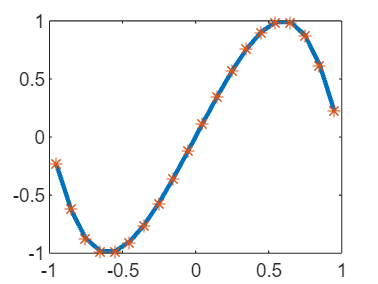

err1 = abs(yy1-yy2);
plot(xx,yy1,'LineWidth',2)
hold on
plot(xx,yy2,'*')

num

num = 20

disp(norm(err1,inf))

    0.0182

